# Enviro Analysis 

Author: M. Noyce

This program extracts the environmental data from the SHARC Buoys  

For reference the depoyment and retrieval times (UTC) were:

**Buoy        Deployment                Retrieval**

SB01        2022-07-19 13:20        2022-07-24 12:25    

SB02        2022-07-19 18:00        N/A

SB03        2022-07-20 01:45        N/A

SB04        2022-07-20 15:40        2022-07-24 07:50  

SB05        2022-07-20 07:40        2022-07-24 14:00  

SB06        2022-07-20 19:10        2022-07-23 09:20

## Import Raw Environmental Data 

outdir = "C:\Users\uctsh\Documents\MATLAB\EnvOutput";
projectdir = "C:\Users\uctsh\Documents\MATLAB\SHARC_BUOY_06_RAW_DATA\ED";
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";

%List wave data folders
folders = dir(projectdir);

%Sort List of folders 
folders = natsortfiles(folders);

%Loop over every folder 
for folderCount = 1 : numel(folders)
    

    concatFile = sprintf("ES%d.txt", folderCount);
    subfolder = sprintf("ES%d", folderCount);
    outFileName = fullfile(outdir, concatFile); 
    outFile = fopen(outFileName, "w");
    
    subfoldername = fullfile(projectdir, subfolder);
    files = dir(subfoldername);
    files = natsortfiles(files);

    %concatenate files in subfolder
    for fileCount = 1 : length(files)
        
        filename = fullfile(subfoldername, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
    end
    
    fclose("all");

end

File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.


## Create Text file with full dataset


outFileName = fullfile(outdir_2, "ES_All.txt"); 
outFile = fopen(outFileName, "w"); 

files = dir(outdir);
files = natsortfiles(files);

%Create concatenated text file with all data
for fileCount = 1 : length(files) 
        
        filename = fullfile(outdir, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
end

File does not exist.
File does not exist.


    
fclose("all");
   

## Read Data into Table 

%Specify variables
opts = delimitedTextImportOptions("NumVariables", 3);
opts.VariableNames = ["TimeUTC","Temperature", "Pressure"];
opts.VariableTypes = ["datetime", "double", "double"];

%Read in table
envfile = fullfile(outdir_2, "ES_All.txt");
ENVTable = readtable(envfile, opts);

## Add dates to Table 

%Data has time but not date values, this code segment adds date values

%Covert Time values in table to datetime format 
ENVTable.TimeUTC = datetime(ENVTable.TimeUTC, 'Format','yyyy-MM-dd HH:mm:ss.SSS');

%calculate new day increment
newday = [true; diff(ENVTable.TimeUTC)<0];
daynum = cumsum(newday);

%Create array of days
date = datetime(2022, 07, 20) + caldays(daynum - 1); 
DateTimeUTC = date + timeofday(ENVTable.TimeUTC);

%Add datetime 
ENVTable = addvars(ENVTable, DateTimeUTC, 'before', "TimeUTC"); 
%WaveTable.TimeUTC = [];

%Specify Times after deployment and before retrieval
ENVTable = ENVTable(ENVTable.DateTimeUTC > datetime(2022, 7, 20, 19, 10, 00), :);
ENVTable = ENVTable(ENVTable.DateTimeUTC < datetime(2022, 7, 23, 9, 20, 00), :);

## Differentiate Time Series on Table

%Add Count Label to differentiate between time series
newTimeSeries= [true; diff(ENVTable.DateTimeUTC)< minutes(25)];
timeSeriesCount = cumsum(newTimeSeries);
TimeSeriesNo = max(timeSeriesCount); 
ENVTable = addvars(ENVTable, timeSeriesCount, 'After', 'DateTimeUTC');

##  Environmental Data Scaling 

%Scaling 
ENVTable.Temperature = ENVTable.Temperature/100; %Scale Temperature to celsius
ENVTable.Pressure = ENVTable.Pressure/1000; %Scale Pressure to kPa

## Plot Data 

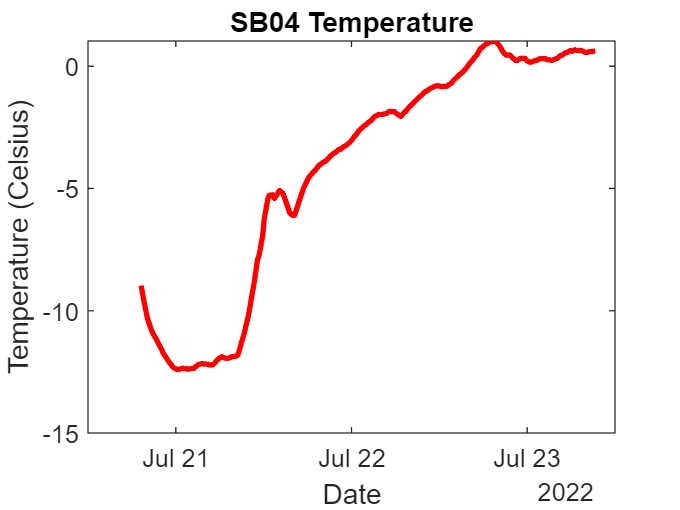

%Plot temperature and pressure data 
plot(ENVTable.DateTimeUTC, ENVTable.Temperature, 'LineWidth', 2, 'Color', 'red');
title("SB04 Temperature");
ylabel("Temperature (Celsius)");
xlabel("Date");

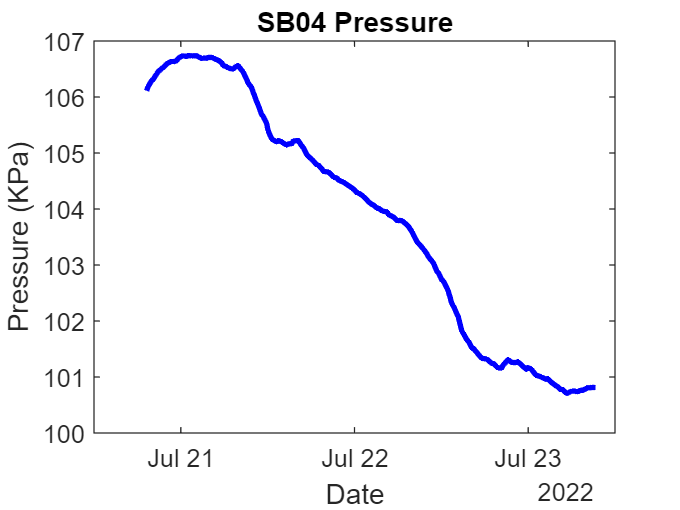


%Plot temperature and pressure data 
plot(ENVTable.DateTimeUTC, ENVTable.Pressure, 'LineWidth', 2, 'Color', 'blue');
title("SB04 Pressure");
ylabel("Pressure (KPa)");
xlabel("Date");

## Plot Data: Multiple TIme Series

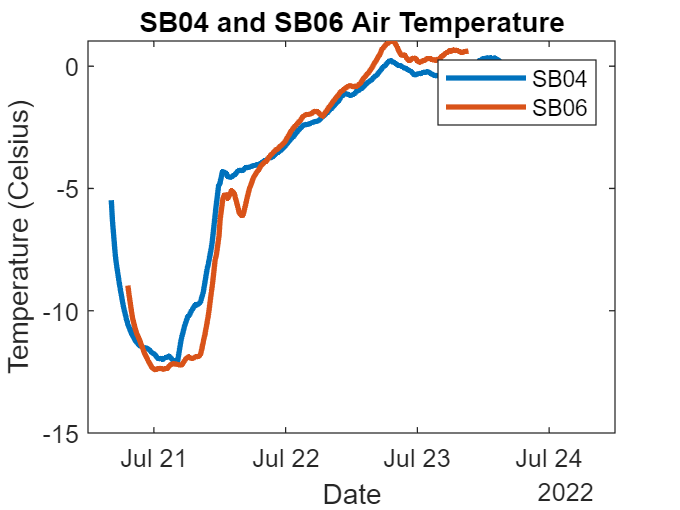

%Store previously processed data from another buoy
%Comment out before using 
%SB04Temp = ENVTable.Temperature(2:end-1);
%SB04Datetime = ENVTable.DateTimeUTC(2:end-1);

%Plot temperature and pressure data 
plot(SB04Datetime, SB04Temp, ENVTable.DateTimeUTC, ENVTable.Temperature, 'LineWidth', 2);
title("SB04 and SB06 Air Temperature");
ylabel("Temperature (Celsius)");
xlabel("Date");
legend("SB04", "SB06");


%Plot temperature and pressure data 
plot(ENVTable.DateTimeUTC, ENVTable.Pressure, 'LineWidth', 2, 'Color', 'blue');
title("SB04 Pressure");
ylabel("Pressure (KPa)");
xlabel("Date");